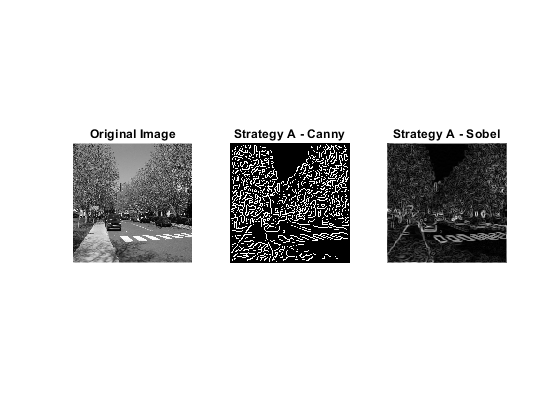


%% IMAGE ENCODING STRATEGIES BEFORE PHOSPHENE GENERATION
%
% Input:
% Grayscale image, 128x128 pixels (reference image)
%
% Output:
% A: Edge representation (Canny and Sobel)
% B: Saliency representation
% C: Main object segmentation
% D: Weighted Sobel-Saliency fusion optimized by Bayesian Optimization
%
% Required toolboxes:
% Image Processing Toolbox
% Machine Vision Toolbox (icanny, isobel)
% Statistics and Machine Learning Toolbox (bayesopt)

clear;
clc;
close all;

%% IMAGE LOADING

chemin = "E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\Images\Outside\ADE_val_00001832_128.png";

img = imread(chemin);

%% STRATEGY A: EDGE DETECTION (CANNY AND SOBEL)

% Canny edge detector
edgeCanny = icanny(img);

% Sobel gradient magnitude
gradSobel = isobel(img);

% Normalize Sobel gradient
gradSobelNorm = mat2gray(double(gradSobel));

% Display
figure('Name','Strategy A - Edge Detection');
subplot(1,3,1);
imshow(img, []);
title('Original Image');

subplot(1,3,2);
imshow(edgeCanny, []);
title('Strategy A - Canny');

subplot(1,3,3);
imshow(gradSobelNorm, []);
title('Strategy A - Sobel');

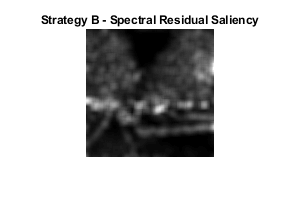

%% STRATEGY B: SALIENCY MAP (SPECTRAL RESIDUAL)
% Method: Hou & Zhang, CVPR 2007

imgD = im2double(img);

% Fourier transform
myFFT = fft2(imgD);

% Log-amplitude and phase spectra
logAmplitude = log(abs(myFFT) + eps);
phase = angle(myFFT);

% Spectral residual
smoothAmplitude = imfilter(logAmplitude, ...
    fspecial('average', 3), 'replicate');

spectralResidual = logAmplitude - smoothAmplitude;

% Reconstruction in spatial domain
saliencyMap = abs(ifft2( ...
    exp(spectralResidual + 1i * phase))).^2;

% Gaussian smoothing
saliencyMap = imfilter(saliencyMap, ...
    fspecial('gaussian', [9 9], 3), 'replicate');

% Normalization [0,1]
saliencyMap = mat2gray(saliencyMap);

% Display in grayscale (no heatmap or overlay)
figure('Name','Strategy B - Saliency');

imshow(saliencyMap, []);
colormap(gray);
title('Strategy B - Spectral Residual Saliency');

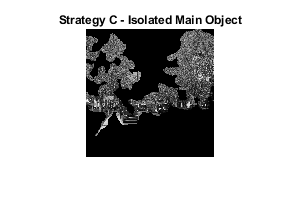


%% STRATEGY C: MAIN OBJECT SEGMENTATION
% Segmentation based on the saliency map from Strategy B

% 1. Automatic Otsu threshold
seuil = graythresh(saliencyMap);
masque = imbinarize(saliencyMap, seuil);

% 2. Mask cleaning
masque = imfill(masque, 'holes');

if any(masque(:))
    masque = bwareafilt(masque, 1);
else
    warning('No object detected in the saliency map.');
end

% 3. Background removal
objetIsole = img .* cast(masque, 'like', img);

% Display

imshow(objetIsole, []);
title('Strategy C - Isolated Main Object');


%% STRATEGY D: WEIGHTED SOBEL + SALIENCY FUSION
% Initial weights: 0.35 Sobel and 0.65 Saliency

I = im2double(img);

G = mat2gray(double(gradSobelNorm));
S = mat2gray(double(saliencyMap));

% Dimension verification
assert(isequal(size(I), size(G), size(S)), ...
    'All images must have the same dimensions.');


%% BAYESIAN OPTIMIZATION

% Optimization variable
alphaVar = optimizableVariable('alpha', [0, 1]);

% Objective function
objective = @(T) fusionObjective(T.alpha, I, G, S);

% Bayesian optimization
results = bayesopt(objective, alphaVar, ...
    'MaxObjectiveEvaluations', 25, ...
    'IsObjectiveDeterministic', true, ...
    'AcquisitionFunctionName', ...
    'expected-improvement-plus', ...
    'PlotFcn', []);

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        alpha |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      0.9397 |   0.0048985 |      0.9397 |      0.9397 |      0.13279 |
|    2 | Accept |     0.95055 |   0.0055597 |      0.9397 |      0.9397 |      0.99266 |
|    3 | Best   |     0.93878 |    0.010205 |     0.93878 |     0.93878 |      0.39199 |
|    4 | Accept |     0.94517 |     0.00442 |     0.93878 |     0.93878 |      0.78597 |
|    5 | Best   |     0.93853 |   0.0050641 |     0.93853 |     0.93853 |      0.30368 |
|    6 | Accept |     0.93853 |   0.0059753 |     0.93853 |     0.93853 |      0.31895 |
|    7 | Best   |     0.93853 |   0.0049834 |     0.93853 |     0.93853 |      0.30795 |
|    8 | Best   |    


%% OPTIMAL FUSION

% Best Sobel weight
alphaBest = results.XAtMinObjective.alpha;

% Best Saliency weight
betaBest = 1 - alphaBest;

% Optimized fusion
pendereBest = alphaBest * G + betaBest * S;

fprintf('\n===== BAYESIAN OPTIMIZATION RESULTS =====\n');


===== BAYESIAN OPTIMIZATION RESULTS =====


fprintf('Optimal Sobel weight: %.4f\n', alphaBest);

Optimal Sobel weight: 0.3082


fprintf('Optimal Saliency weight: %.4f\n', betaBest);

Optimal Saliency weight: 0.6918


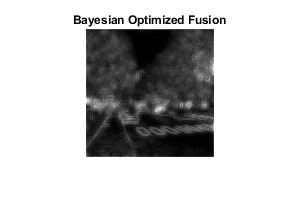

%% DISPLAY FINAL RESULTS

imshow(pendereBest, []);
title('Bayesian Optimized Fusion');


%% OBJECTIVE FUNCTION


function loss = fusionObjective(alpha, I, G, S)

    % Weighted fusion
    P = alpha * G + (1-alpha) * S;

    % Structural similarity
    similarity = ssim(P, I);

    % Bayesian optimization minimizes the loss
    loss = 1 - similarity;

end
